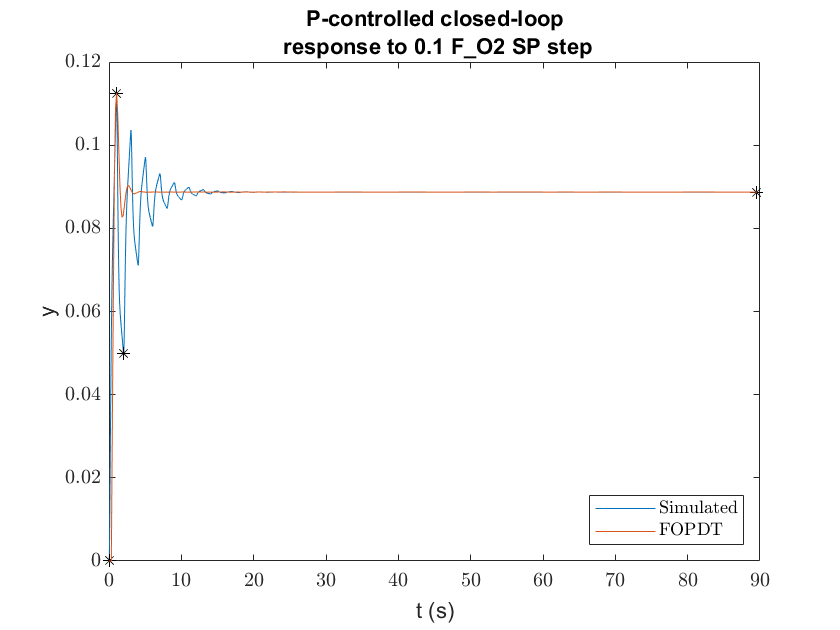

% This script executes the SIMC tuning method. It first creates a FOPDT
% approximation, and then uses the SIMC rules to estimate the desired
% tuning parameters. The configurable parameters, Tc, is then varied over a
% range specified, and the resulting performance is evaluated.
%
% This script saves its result to workspace, and reloads it to not have to
% redo all the work. To start over, set reset_all to true.
%
% The script assumes the following variables are defined in the workspace:
%
%   ss_state:   ModelOperatingPoint representing a steady state of the
%               system. Do
%                   >> FurnaceParamters; 
%                   >> ss_state = create_ss_state(12000);
%               to create it from scratch, and then do
%                   >> simOut = sim_from_ss(ss_state, 1000);
%                   >> ss_state = simOut.ss_state_out;
%               to ensure that the controller also has settled.
%
%   simOut:     SimulationOutput gathered when creating the 30% overshoot
%               setpoint step response. Note that simOut should have been
%               created from the same state as the ss_state that is used
%               here. The simOut simulation time interval should only
%               include the fastest dynamics of the reponse. If the
%               simulation time is too high, the FOPDT model will be poor.First, 
%               review the "reg" struct in FurnaceParameters containing controller
%               settings. I is vital that you review which
%               signals are set to Controlled and which are set to Constant.
%               Furthermore, you must check that the tuning parameters are set
%               correctly, and in particular that the tuning parameters for the
%               controller to be calculated have zero integral gain, zero derivative
%               gain and a proportional gain creating approximately 30% overshoot.
%               Increase the corresponding setpoint variable, and when you have chosen
%               a Kp such that you think you will get 30% overshoot, do
%                   >> FurnaceParamters;
%                   >> simOut = sim_from_ss(ss_state, 4000);
%               where ss_state was created as described above. If there is
%               not 30% overshoot, change FurnaceParameters and try again.
%               When you have a proper simOut, you can run this script.

clf;
warning('off','all');
FurnaceParameters;

%%% Begin configuration %%%

sp_name = "AB";                     % Controller setpoint name prefix
pid_name = "AB_HHV";                % Controller PID parameter name prefix
dsp = 0.1;                          % The setpoint change used when creating closed-loop response
nths = [1 2 4 8 16 24 32 40 48 64]; % List of SIMC Tcs to be evaluated. Given as number of thetas.
reset_all = false;                  % Set to true if you want to clear all tuning data.
estimate_ss = false;                % Set to true if you want to approximate the steady-state response
                                    % to the 30% overshoot response. You should try this if the FOPDT
                                    % estimate is bad.

%%% End configuration %%%

% Initialize cell arrays. Note that elements in responses, tunings and performances with the same
% index in the cell arrays are assumed to represent the same tuning.
if reset_all || ~(exist("responses"))
    responses = {};                 % Contains the setpoint change responses for the different tunings
end
if reset_all || ~(exist("tunings"))
    tunings = {};                   % Contains structs with tuning paremeters for the different tunings
end
performances = {};                  % Containts structs with tuning performance data

% Read data from workspace
[y, ty, ~, ~] = load_data(pid_name, simOut);
eval(sprintf('Kc0 = reg.Kp_%s;', pid_name));
eval(sprintf('sp = reg.sp_%s;', sp_name));
dt = ty - ty(1);

% Create SIMC approximation
y0 = y(1);                          % Initial y
yf = y(length(y));                  % Final y
yp = max(y);                        % Peak y

dys = dsp;                          % Setpoint change
tp_idx = find(y == yp, 1);          % Peak index
tp = dt(tp_idx);                    % Peak time
y2 = y(tp_idx:length(y));           % Reponse after peak
yu = min(y2);                       % Undershoot y
dyp = yp - y0;                      % Overshoot delta
dyu = yu - y0;                      % Undershoot delta
tu_idx = find(y2 == yu, 1);         % Undershoot index
tu = dt(tp_idx + tu_idx - 1);       % Undershoot time
if estimate_ss
    dyf = min(0.45 * (dyp + dyu));  % Estimate the steady-state response
else
    dyf = yf - y0;                  % Use the actual steady-state response
end


%

% Calulate FOPDT parameters
D = (dyp - dyf) / dyf;
B = abs((dys - dyf)/dyf);
A = 1.152*D^2 - 1.607*D + 1;
r = 2*A/B;
K = 1/(Kc0 * B);
th = tp * (0.309 + 0.209*exp(-0.61*r));
T1 = r * th;

% Create FOPDT state-space model
s = tf('s');
G = exp(-th * s) * K / (1 + T1 * s);
C = Kc0;
H = feedback(C*G, 1);
Hs = dys * H;

% Get estimated FOPDT setpoint step response
[yc_est, dt_est] = step(Hs, dt(length(dt)));
yc_est = yc_est + y0;

% Plot the actual 30% overshoot response
figure();
plot(dt, y-y0);
hold on;
% Plot the analyzed points
plot(tp, yp-y0, 'k*', 'HandleVisibility','off');
plot(tu, yu-y0, 'k*', 'HandleVisibility','off');
plot(dt(length(dt)), y0 + dyf-y0, 'k*', 'HandleVisibility','off');
plot(0, y0-y0, 'k*', 'HandleVisibility','off');
% Plot the estimated FOPDT response
plot(dt_est, yc_est-y0);
title(sprintf('P-controlled closed-loop\n response to %.1f %s SP step', dys, sp_name), 'Interpreter', 'none');
legend('Simulated', 'FOPDT', 'Location', 'southeast');
xlabel('t (s)');
ylabel('y');
hold off;

-->Converting model to discrete time.
-->The "Model.Noise" property of the "mpc" object is empty. Assuming white noise on each measured output channel.


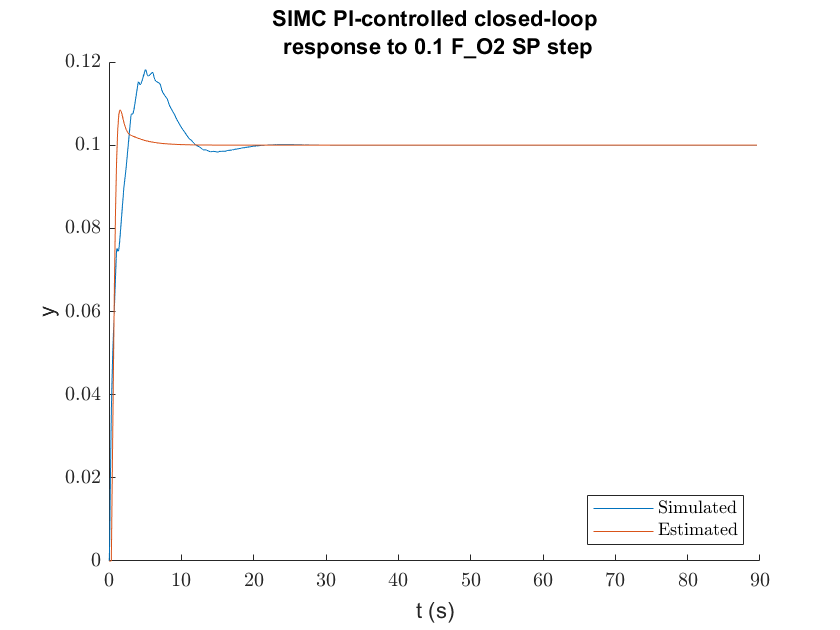

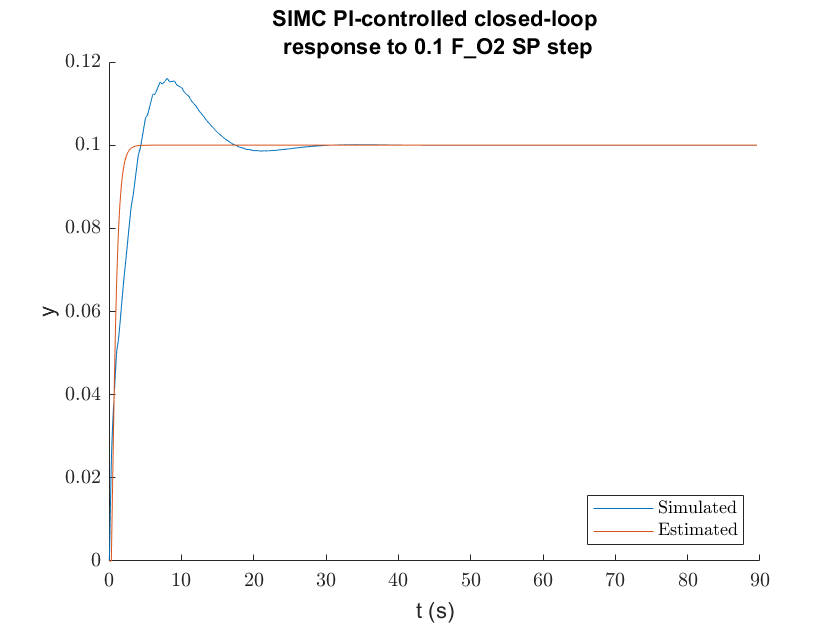

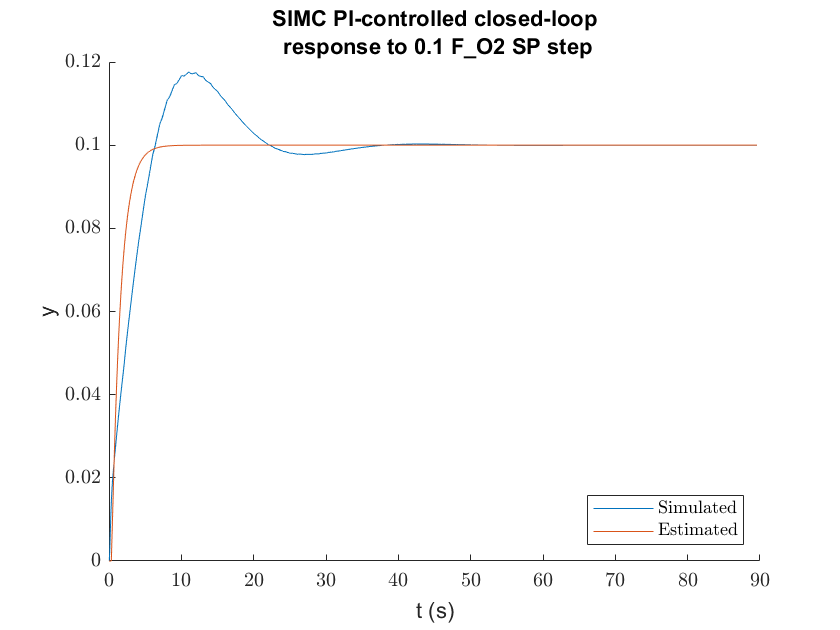

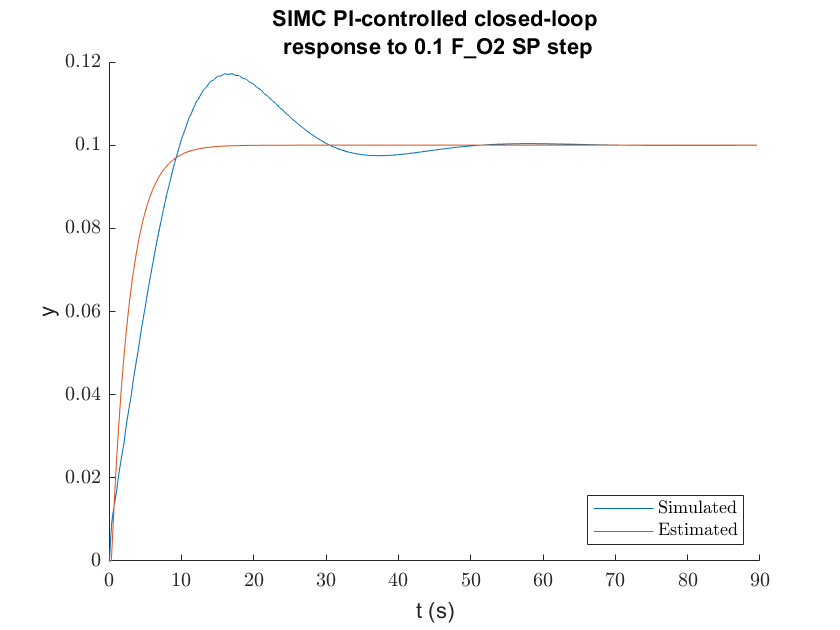

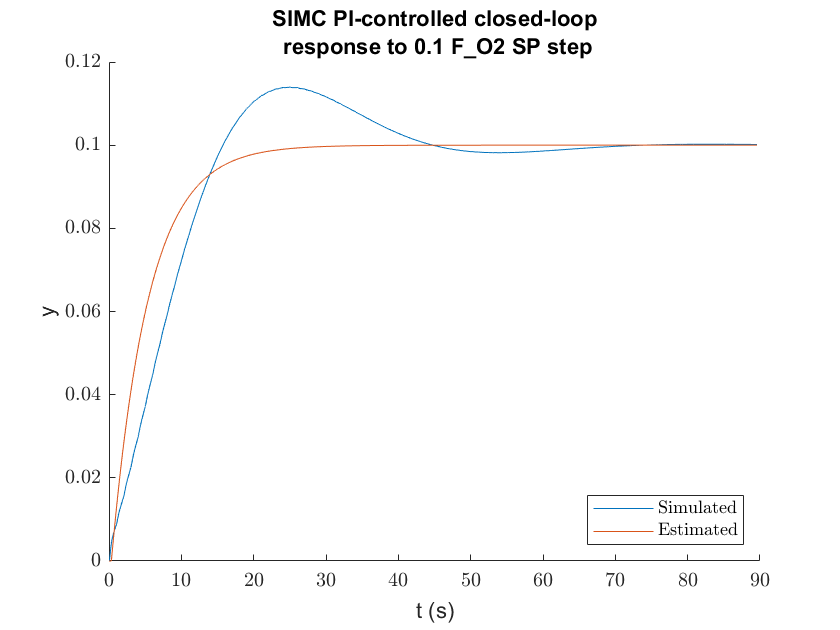

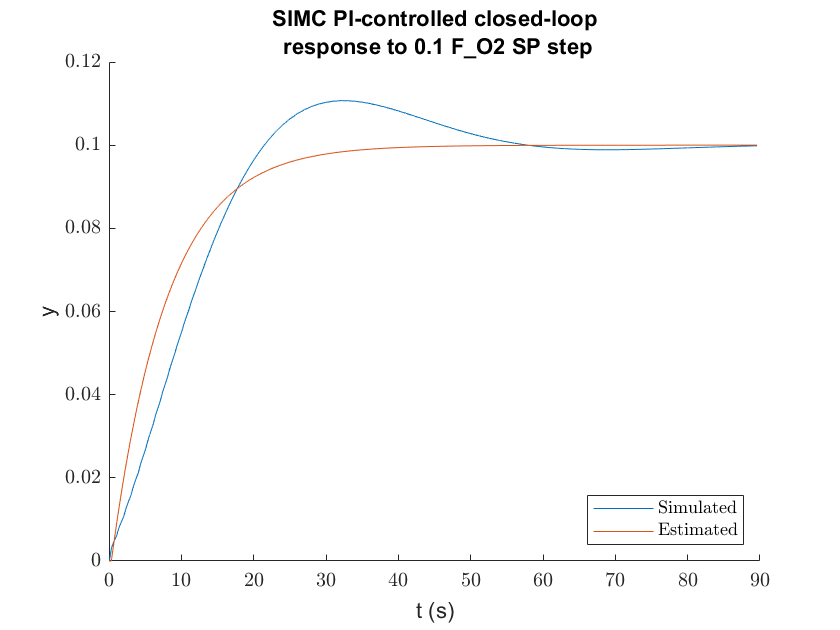

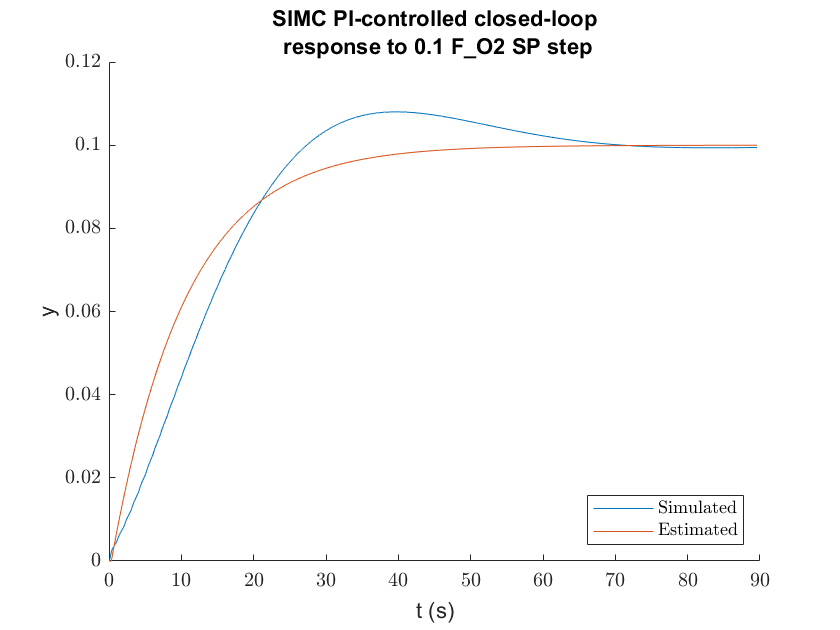

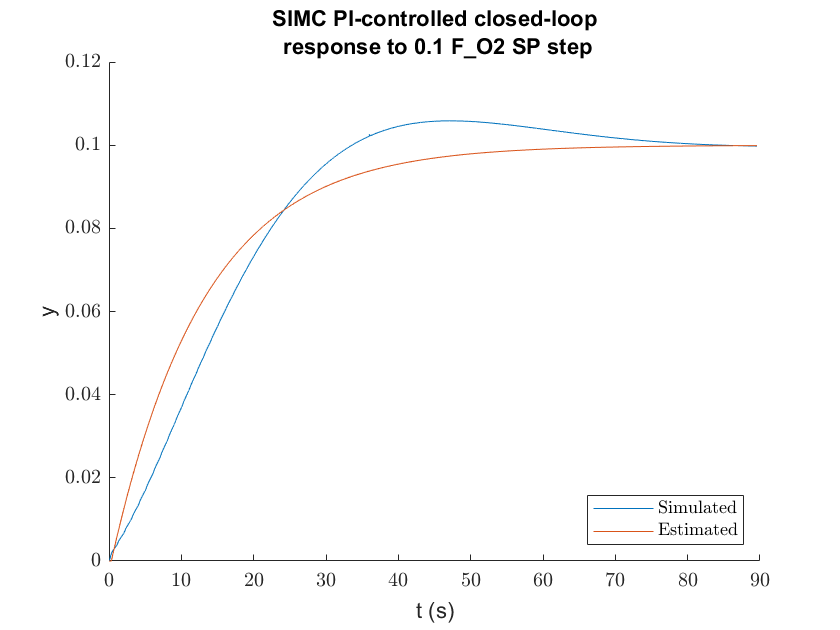


% Iterate over the given Tcs
for i = 1:length(nths)
    nth = nths(i);
    
    % If we already have calculated tuning parameters for a Tc
    % in a previous run, don't recalculate it.
    skip = false;
    for j = 1:length(tunings)
        if tunings{j}.nth == nth
            fprintf("Skipping nth = %.2e.", nth);
            skip = true;
            break
        end
    end
    if skip
        continue
    end
    
    % Calculate SIMC parameters
    Tc = nth*th;                        % The SIMC Tc
    Kp = 1/K * T1/(Tc + th);            % The P parameter
    Ti = min(T1, 4*(Tc + th));          % The integral time
    Ki = Kp/Ti;                         % The I parameter for a PID in parallell form
        
    C_SIMC = Kp + Ki/s;                 % PI block for closed-loop response prediction
    H_SIMC = feedback(C_SIMC*G, 1);     % Total transfer function
    
    % Plot the 
    [yc_SIMC, dt_SIMC] = step(dys * H_SIMC, dt(length(dt)));
    yc_SIMC = yc_SIMC + y0;
    
    % Activate the PID parameters to be tested.
    eval(sprintf('reg.Kp_%s = Kp;', pid_name));
    eval(sprintf('reg.Ki_%s = Ki;', pid_name));
    
    % Do a closed-loop simulation with the new parameters.
    set_param(...
        'Furnace',...
        'LoadInitialState', 'on',...
        'InitialState', 'ss_state'...
    );
    simOut_tuned = sim(...
        'Furnace',...
        'StartTime', sprintf('%d', ty(1)),...
        'StopTime', sprintf('%d', ty(end))...
    );
    % Load the resulting response
    [y_real, ty_real, us_real, tus_real] = load_data(pid_name, simOut_tuned);
    dt_real = ty_real-ty_real(1);
    
    % Plot the estimated and actual response
    figure();
    title(sprintf('SIMC PI-controlled closed-loop\n response to %.1f %s SP step', dys, sp_name), 'Interpreter', 'none');
    xlabel('t (s)');
    ylabel('y');
    hold on;
    plot(dt_real, y_real-y0);
    plot(dt_SIMC, yc_SIMC-y0);
    legend('Simulated', 'Estimated', 'Location', 'southeast');
    
    % Save data to workspace
    clearvars response;
    response.y = y_real;            % Simulated response
    response.ty = ty_real;          % Simulated response time
    response.us = us_real;          % Simulated input usage
    response.tus = tus_real;        % Simulated input usage time
    responses{end+1} = response;
    
    clearvars tuning;
    tuning.nth = nth;               % Number of thetas in Tc
    tuning.Kc0 = Kc0;               % The critical P-parameter used
    tuning.dsp = dsp;               % The setpoint step used
    tuning.y0 = y0;                 % The inital y
    tuning.sp = sp;                 % The base setpoint used
    tuning.Kp = Kp;                 % The SIMC P-parameter
    tuning.Ki = Ki;                 % The SIMC I-parameter
    tunings{end+1} = tuning;
end

    "============================"



tuning = struct with fields:
    nth: 1
    Kc0: 34
    dsp: 0.1000
     y0: 4.6345
     sp: 4.7345
     Kp: 22.2003
     Ki: 8.6393


performance = struct with fields:
                nth: 1
                iae: 0.1822
            rel_iae: 1.8223
                ise: 0.0054
            rel_ise: 0.0542
          overshoot: 0.0182
                sse: 8.7670e-08
            rel_sse: 8.7670e-07
      rel_overshoot: 0.1824
    max_input_usage: [16.3167 18 0.0025 4]
    min_input_usage: [14.0006 18 0.0025 4]
          rise_time: 2.0743
      settling_time: 10.8870


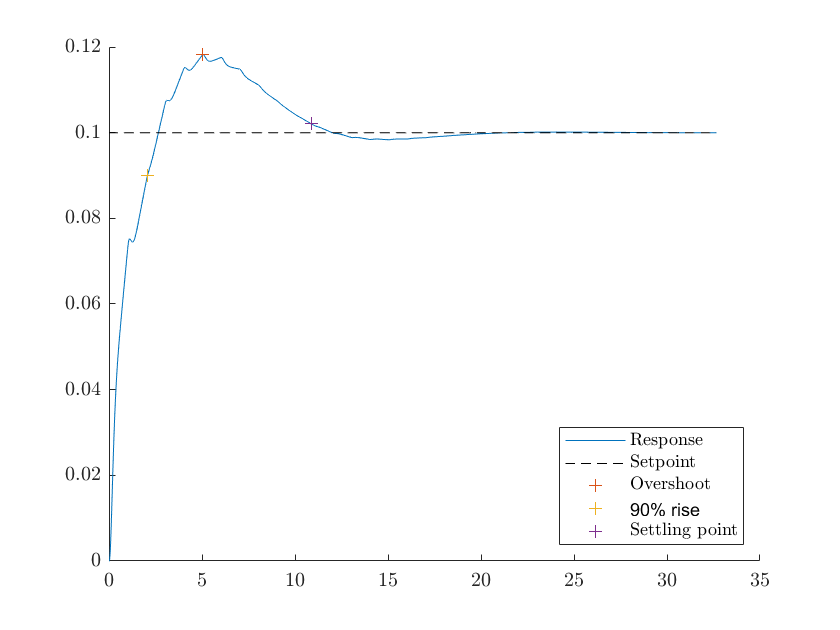

    "============================"



tuning = struct with fields:
    nth: 2
    Kc0: 34
    dsp: 0.1000
     y0: 4.6345
     sp: 4.7345
     Kp: 14.8002
     Ki: 4.4858


performance = struct with fields:
                nth: 2
                iae: 0.2733
            rel_iae: 2.7332
                ise: 0.0092
            rel_ise: 0.0923
          overshoot: 0.0160
                sse: 1.8671e-07
            rel_sse: 1.8671e-06
      rel_overshoot: 0.1603
    max_input_usage: [15.5448 18 0.0025 4]
    min_input_usage: [14.0006 18 0.0025 4]
          rise_time: 3.5011
      settling_time: 15.7074


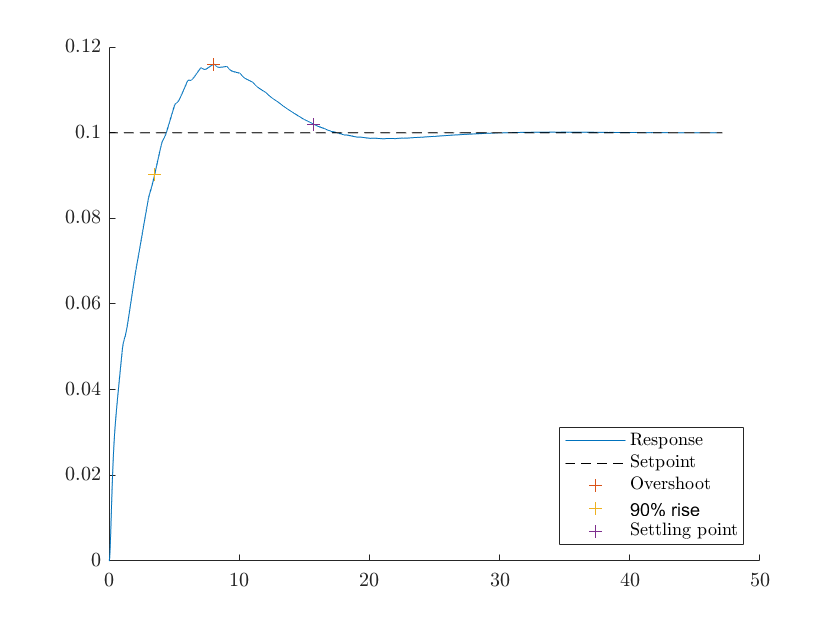

    "============================"



tuning = struct with fields:
    nth: 4
    Kc0: 34
    dsp: 0.1000
     y0: 4.6345
     sp: 4.7345
     Kp: 8.8801
     Ki: 2.6915


performance = struct with fields:
                nth: 4
                iae: 0.4303
            rel_iae: 4.3034
                ise: 0.0165
            rel_ise: 0.1650
          overshoot: 0.0176
                sse: -2.5721e-07
            rel_sse: -2.5721e-06
      rel_overshoot: 0.1760
    max_input_usage: [14.9478 18 0.0025 4]
    min_input_usage: [14.0006 18 0.0025 4]
          rise_time: 5.2758
      settling_time: 29.2320


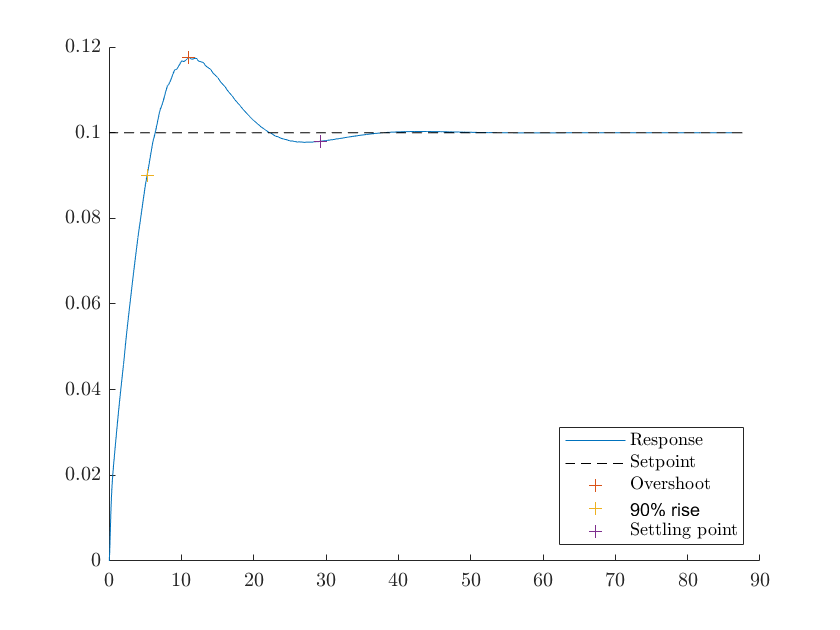

    "============================"



tuning = struct with fields:
    nth: 8
    Kc0: 34
    dsp: 0.1000
     y0: 4.6345
     sp: 4.7345
     Kp: 4.9334
     Ki: 1.4953


performance = struct with fields:
                nth: 8
                iae: 0.6600
            rel_iae: 6.6003
                ise: 0.0285
            rel_ise: 0.2851
          overshoot: 0.0172
                sse: -1.0251e-05
            rel_sse: -1.0251e-04
      rel_overshoot: 0.1720
    max_input_usage: [14.7509 18 0.0025 4]
    min_input_usage: [14.0006 18 0.0025 4]
          rise_time: 8.2462
      settling_time: 41.3424


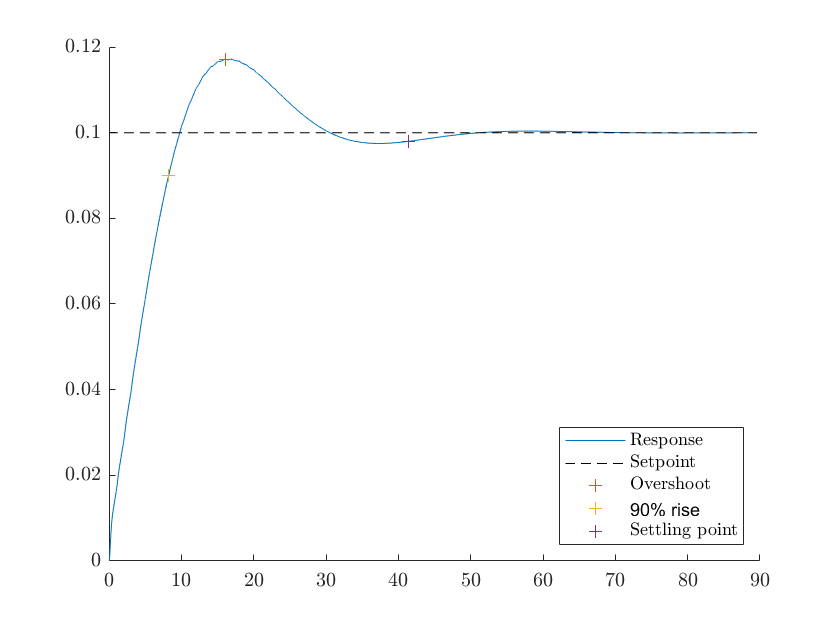

    "============================"



tuning = struct with fields:
    nth: 16
    Kc0: 34
    dsp: 0.1000
     y0: 4.6345
     sp: 4.7345
     Kp: 2.6118
     Ki: 0.7916


performance = struct with fields:
                nth: 16
                iae: 0.9654
            rel_iae: 9.6538
                ise: 0.0474
            rel_ise: 0.4744
          overshoot: 0.0140
                sse: 1.7479e-04
            rel_sse: 0.0017
      rel_overshoot: 0.1397
    max_input_usage: [14.6102 18 0.0025 4]
    min_input_usage: [14.0006 18 0.0025 4]
          rise_time: 13.2812
      settling_time: 40.9302


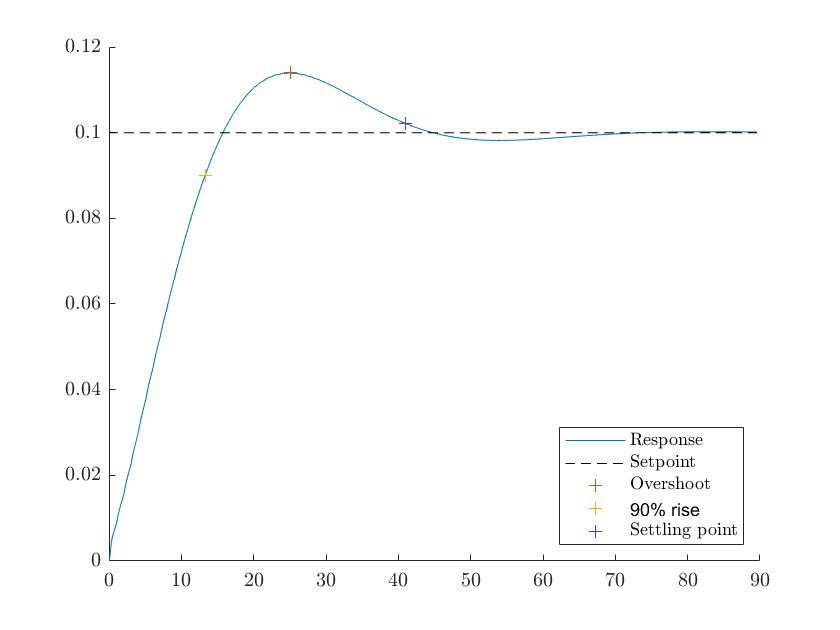

    "============================"



tuning = struct with fields:
    nth: 24
    Kc0: 34
    dsp: 0.1000
     y0: 4.6345
     sp: 4.7345
     Kp: 1.7760
     Ki: 0.5383


performance = struct with fields:
                nth: 24
                iae: 1.1920
            rel_iae: 11.9195
                ise: 0.0635
            rel_ise: 0.6352
          overshoot: 0.0107
                sse: -1.4544e-04
            rel_sse: -0.0015
      rel_overshoot: 0.1073
    max_input_usage: [14.5465 18 0.0025 4]
    min_input_usage: [14.0006 18 0.0025 4]
          rise_time: 17.8799
      settling_time: 52.1267


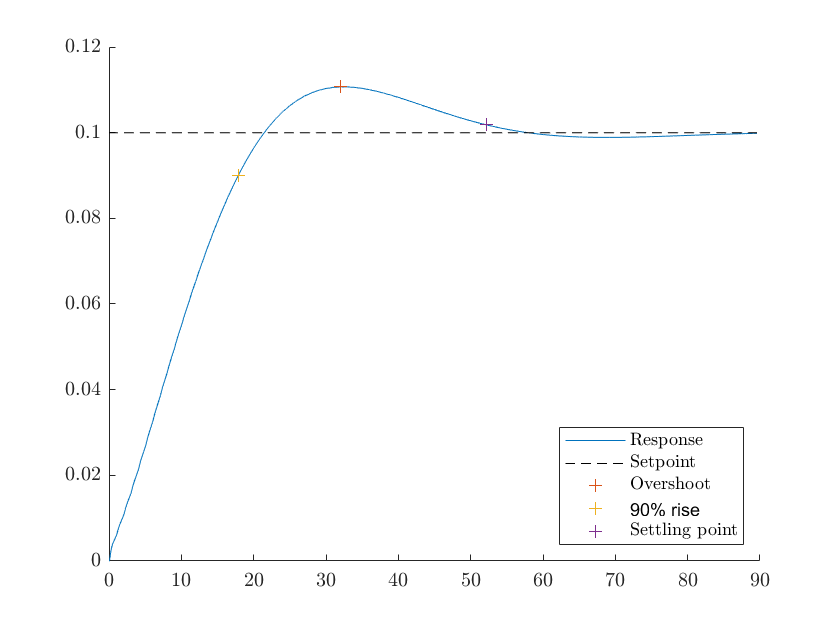

    "============================"



tuning = struct with fields:
    nth: 32
    Kc0: 34
    dsp: 0.1000
     y0: 4.6345
     sp: 4.7345
     Kp: 1.3455
     Ki: 0.4078


performance = struct with fields:
                nth: 32
                iae: 1.3870
            rel_iae: 13.8700
                ise: 0.0784
            rel_ise: 0.7837
          overshoot: 0.0080
                sse: -5.4310e-04
            rel_sse: -0.0054
      rel_overshoot: 0.0804
    max_input_usage: [14.5088 18 0.0025 4]
    min_input_usage: [14.0006 18 0.0025 4]
          rise_time: 22.3443
      settling_time: 63.0327


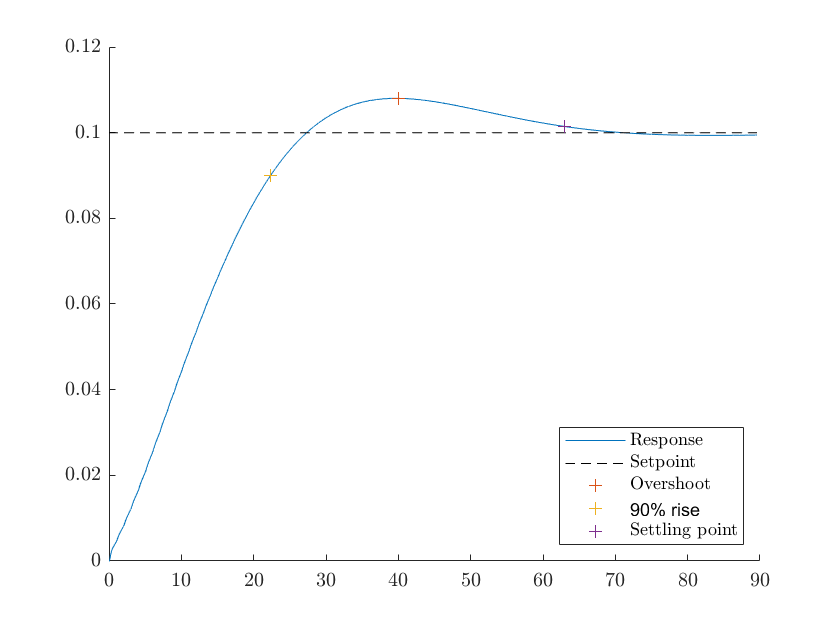

    "============================"



tuning = struct with fields:
    nth: 40
    Kc0: 34
    dsp: 0.1000
     y0: 4.6345
     sp: 4.7345
     Kp: 1.0829
     Ki: 0.3282


performance = struct with fields:
                nth: 40
                iae: 1.5744
            rel_iae: 15.7437
                ise: 0.0926
            rel_ise: 0.9257
          overshoot: 0.0059
                sse: -2.1430e-04
            rel_sse: -0.0021
      rel_overshoot: 0.0587
    max_input_usage: [14.4840 18 0.0025 4]
    min_input_usage: [14.0006 18 0.0025 4]
          rise_time: 26.8177
      settling_time: 69.7780


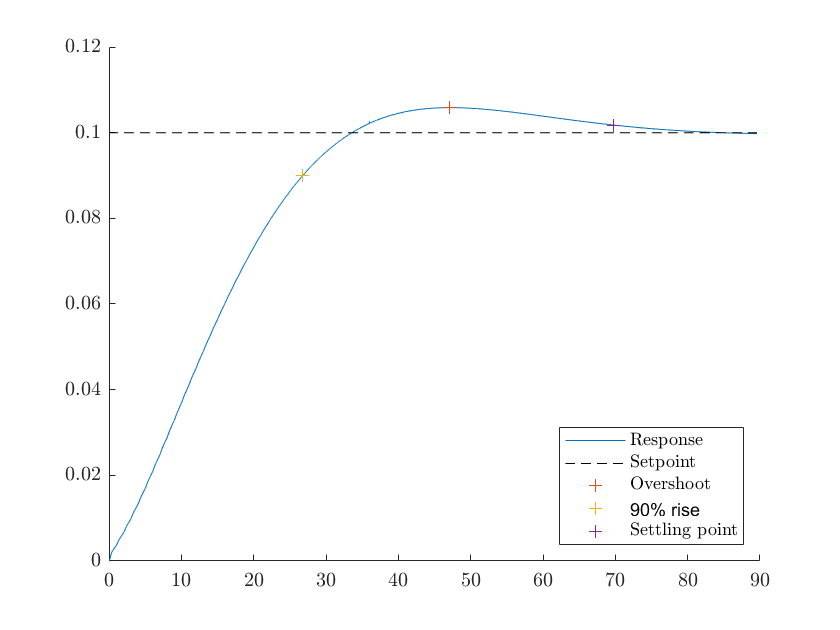

    "============================"



tuning = struct with fields:
    nth: 48
    Kc0: 34
    dsp: 0.1000
     y0: 4.6345
     sp: 4.7345
     Kp: 0.9061
     Ki: 0.2746


performance = struct with fields:
                nth: 48
                iae: 1.7643
            rel_iae: 17.6431
                ise: 0.1064
            rel_ise: 1.0640
          overshoot: 0.0041
                sse: 4.6613e-04
            rel_sse: 0.0047
      rel_overshoot: 0.0415
    max_input_usage: [14.4669 18 0.0025 4]
    min_input_usage: [14.0006 18 0.0025 4]
          rise_time: 31.3240
      settling_time: 71.1636


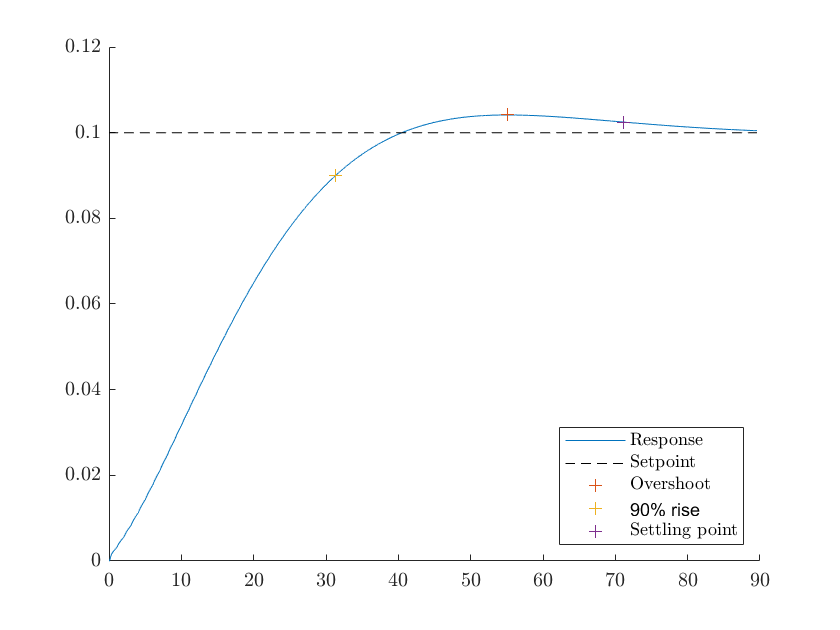

    "============================"



tuning = struct with fields:
    nth: 64
    Kc0: 34
    dsp: 0.1000
     y0: 4.6345
     sp: 4.7345
     Kp: 0.6831
     Ki: 0.2070


performance = struct with fields:
                nth: 64
                iae: 2.1427
            rel_iae: 21.4273
                ise: 0.1334
            rel_ise: 1.3339
          overshoot: 0.0018
                sse: 0.0012
            rel_sse: 0.0123
      rel_overshoot: 0.0178
    max_input_usage: [14.4463 18 0.0025 4]
    min_input_usage: [14.0006 18 0.0025 4]
          rise_time: 40.7823
      settling_time: 54.8300


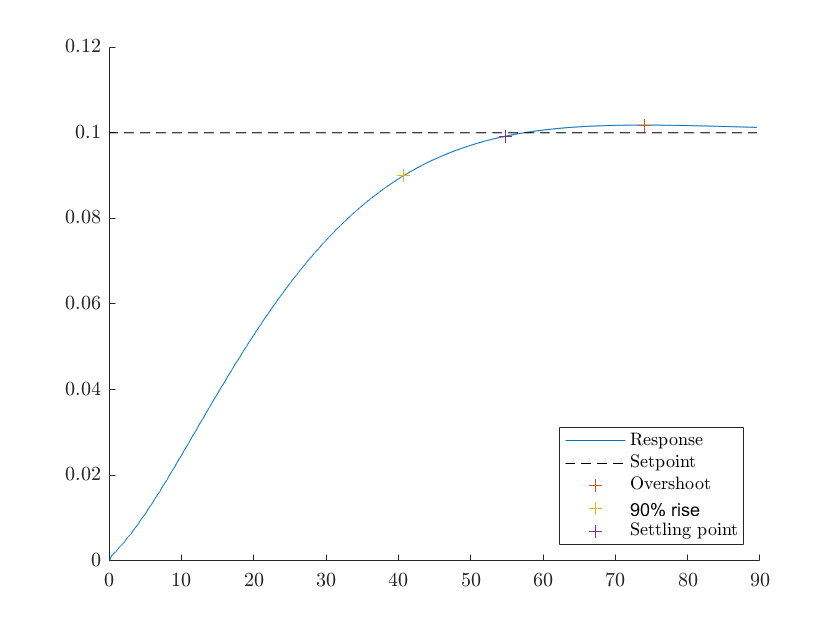


% Iterate over tuning data saved to workspace
for i = 1:length(tunings)
    nth = tunings{i}.nth;
    
    % If we already have performance data for this tuning, skip it.
    skip = false;
    for j = 1:length(performances)
        if performances{j}.nth == nth
            display(sprintf("Skipping nth = %.2e.", nth));
            skip = true;
            break
        end
    end
    if skip
        continue
    end
    
    % Display tuning data
    tuning = tunings{i};
    display("============================");
    display(tuning);
    % Calculate, display and save tuning performance
    response = responses{i};
    performance = analyze_tuning(tuning, response);
    performances{end+1} = performance;
end

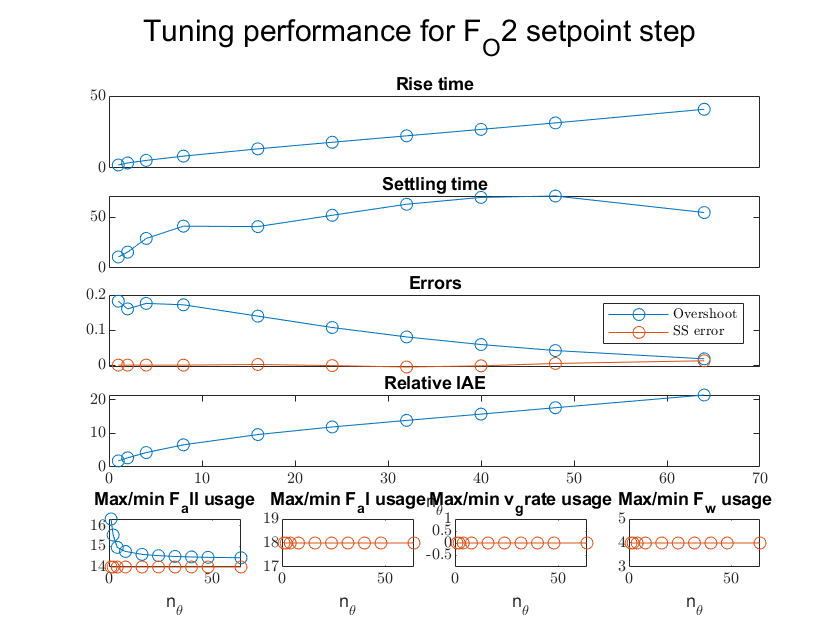


rise_times = [];                % Time to reach first 90% of steady-state response
settling_times = [];            % Time to settle within 5% of steady-state response
rel_overshoots = [];            % Relative overshoot
rel_sses = [];                  % Relative steady-state deviation from setpoint
rel_iaes = [];                  % Relative integrated absolute error
rel_ises = [];                  % Relative integrated square error
max_inputs = {[] [] [] []};     % Max input usage
min_inputs = {[] [] [] []};     % Min input usage

% Iterate over saved performances and prepare them for plotting.
for i = 1:length(nths)
    performance = performances{i};
    rise_times(end+1) = performance.rise_time;
    settling_times(end+1) = performance.settling_time;
    rel_overshoots(end+1) = performance.rel_overshoot;
    rel_sses(end+1) = performance.rel_sse;
    rel_iaes(end+1) = performance.rel_iae;
    rel_ises(end+1) = performance.rel_ise;
    
    for i = 1:4
        max_inputs{i}(end+1) = performance.max_input_usage(i);
        min_inputs{i}(end+1) = performance.min_input_usage(i);
    end
end

% Plot the performances

figure();

subplot(5,4,1:4);
plot(nths, rise_times, '-o');
title('Rise time');
set(gca,'XTick',[]);

subplot(5,4,5:8);
plot(nths, settling_times, '-o');
title('Settling time');
set(gca,'XTick',[]);

subplot(5,4,9:12);
plot(nths, rel_overshoots, '-o');
hold on;
plot(nths, rel_sses, '-o');
hold off;
title('Errors');
legend('Overshoot', 'SS error');
set(gca,'XTick',[]);

subplot(5,4,13:16);
plot(nths, rel_iaes, '-o');
title('Relative IAE');
xlabel("n_{\theta}");

for i = 1:4
    subplot(5,4,17+i-1);
    plot(nths, max_inputs{i}, '-o');
    hold on;
    plot(nths, min_inputs{i}, '-o');
    hold off;
    title(sprintf("Max/min %s usage", reg.MV_names(i)));
xlabel("n_{\theta}");
end

sgtitle(sprintf("Tuning performance for %s setpoint step", sp_name));

% Analyze and plot the performance of a specific tuning.
%
% Inputs
%   tuning:   Struct containing tuning data.
%   response: Struct containing response data for this tuning.
%
% Outputs
%   performance: Struct containing the performance of this tuning.
%

function [performance] = analyze_tuning(tuning, response)
    
    % Extrace response and tuning data
    y = response.y;
    ty = response.ty;
    dty = ty - ty(1);
    us = response.us;
    tus = response.tus;
    performance.nth = tuning.nth;

    % Analyze performance
    performance.iae = trapz(dty, abs(tuning.sp-y));
    performance.rel_iae = performance.iae/tuning.dsp;
    performance.ise =  trapz(dty, (tuning.sp-y).^2);
    performance.rel_ise = performance.ise/tuning.dsp;
    performance.overshoot = max(y-tuning.sp);
    performance.sse = y(end) - tuning.sp;
    performance.rel_sse = performance.sse/tuning.dsp;
    performance.rel_overshoot = performance.overshoot/tuning.dsp;
    performance.max_input_usage = [];
    performance.min_input_usage = [];
    for i = 1:4
        performance.max_input_usage(i) = max(us{i});
        performance.min_input_usage(i) = min(us{i});
    end
    
    overshoot_idx = find(y == performance.overshoot+tuning.sp, 1);
    overshoot_time = dty(overshoot_idx);
    
    rise_idx = find(y-tuning.y0 >= 0.9*(tuning.sp-tuning.y0), 1);
    performance.rise_time = dty(rise_idx);
    
    settling_idx = find(abs(y-y(end)) >= 0.02*(y(end)-tuning.y0), 1, 'last');
    performance.settling_time = dty(settling_idx);
    
    % Prepare to plot the response
    dt_end = performance.settling_time * 3; % There's no point in plotting more than 3 settling times.
    plot_end_idx_y = find(dty <= dt_end, 1, 'last');
    y_plot = y(1:plot_end_idx_y);
    dty_plot = dty(1:plot_end_idx_y);
    
    % Plot the response with analysis points
    display(performance);
    figure();
    hold on;
    plot(dty_plot, y_plot-tuning.y0);
    plot(dty_plot, repmat(tuning.sp-tuning.y0, 1, length(dty_plot)), 'k--');
    plot(overshoot_time, y(overshoot_idx)-tuning.y0, '+');
    plot(performance.rise_time, y(rise_idx)-tuning.y0, '+');
    plot(performance.settling_time, y(settling_idx)-tuning.y0, '+');
    legend('Response', 'Setpoint', 'Overshoot', '90% rise', 'Settling point', 'Location', 'southeast');
    
    hold off;
end